% =========================================================================
% SCRIPT MATLAB: Análise do Sistema Sem Controlador (Planta Gvd e Sensor H)
% Baseado no método e comandos do livro "Controlador PID" (Ogata)
% Unidades explícitas: Tempo em segundos (s), Eixos do plano complexo em s^{-1} 
% =========================================================================

clear; clc; close all;

% 1. Definir a variável de Laplace 's' (unidade: s^{-1})
s = tf('s');

% 2. Declarar a função de transferência da planta Gvd(s)
num_Gvd = 1.984e11;
den_Gvd = [1, 1.332e5, 3.968e9];
Gvd = tf(num_Gvd, den_Gvd);

% 3. Declarar a função de transferência do filtro/sensor H(s)
num_H = 9.87e8;
den_H = [1, 5.441e4, 9.87e8];
H = tf(num_H, den_H);

% =========================================================================
% PARTE A: Resposta ao Degrau (Malha Fechada com C(s) = 1)
% O comando 'feedback' resolve a realimentação fechada do diagrama de blocos:
% T(s) = Gvd(s) / (1 + Gvd(s)*H(s)) [considerando C(s) = 1]
% =========================================================================
T = feedback(Gvd, H);

% Extrair informações de desempenho transitório 
% (Nota: A geração do aviso "Simulation did not reach steady state" ocorre 
% porque o sistema sem controlador é instável e a resposta diverge).
informacoes = stepinfo(T);


fprintf('--- ANÁLISE DE MALHA FECHADA (SEM CONTROLADOR) ---\n');

--- ANÁLISE DE MALHA FECHADA (SEM CONTROLADOR) ---


disp('Se o sistema for instável, o tempo de assentamento diverge ou é inválido.');

Se o sistema for instável, o tempo de assentamento diverge ou é inválido.


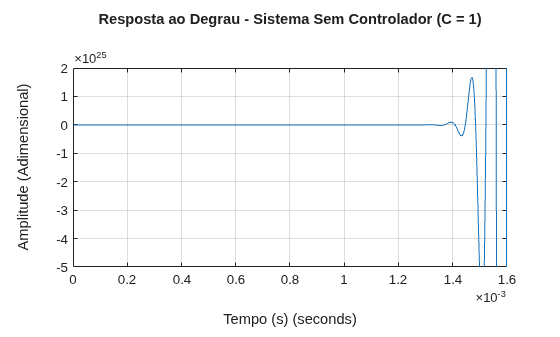


% Plotar a Resposta ao Degrau com unidades explícitas nos eixos
figure('Name', 'Resposta ao Degrau - Malha Fechada', 'Color', 'w');
step(T);
grid on;
title('Resposta ao Degrau - Sistema Sem Controlador (C = 1)');
xlabel('Tempo (s)');
ylabel('Amplitude (Adimensional)');

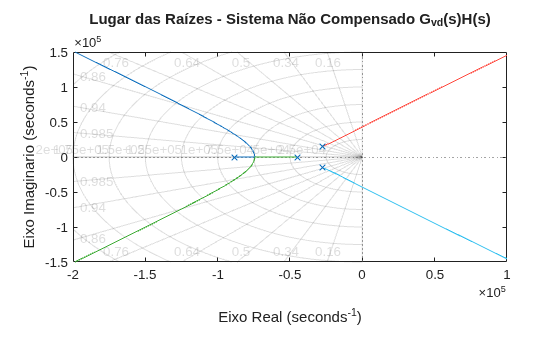


% =========================================================================
% SCRIPT MATLAB: Lugar das Raízes com Linhas do Sgrid e Sem Números
% =========================================================================

% 1. Definir a variável de Laplace 's'
s = tf('s');

% 2. Declarar a função de transferência da planta Gvd(s)
num_Gvd = 1.984e11;
den_Gvd = [1, 1.332e5, 3.968e9];
Gvd = tf(num_Gvd, den_Gvd);

% 3. Declarar a função de transferência do filtro/sensor H(s)
num_H = 9.87e8;
den_H = [1, 5.441e4, 9.87e8];
H = tf(num_H, den_H);

% 4. Definir a malha aberta L(s) = Gvd(s) * H(s)
L = Gvd * H;

% 5. Plotar o Lugar das Raízes
figure('Name', 'Lugar das Raízes', 'Color', 'w');
rlocus(L);
grid on; 
sgrid; % Desenha as linhas e os números de amortecimento/frequência

% 6. Ocultar todos os textos gerados pelo sgrid (números das curvas)
hText = findall(gca, 'Type', 'text');
set(hText, 'Visible', 'off');

% 7. Rótulos dos eixos principais
xlabel('Eixo Real');
ylabel('Eixo Imaginario');
title('Lugar das Raízes - Sistema Não Compensado G_{vd}(s)H(s)');